clear

## Setup: Load Data and Calculate Returns

%Load daily and weekly data (Data.xlsx) on USD/SEK and EUR/SEK
DataDaily = readtable("Data.xlsx", ...
    "Sheet", "Daily", ...
     "DataRange","A2:C5196");
DataWeekly = readtable("Data.xlsx", ...
    "Sheet", "Weekly", ...
    "DataRange","A2:C1041");

DataDaily.Properties.VariableNames = ["Timestamp", "USDSEK", "EURSEK"];
DataWeekly.Properties.VariableNames = ["Timestamp", "USDSEK", "EURSEK"];

% Calculate logarithmic returns 
% Weekly Returns
r_usd_w = diff(log(DataWeekly.USDSEK));
r_eur_w = diff(log(DataWeekly.EURSEK));

% Daily Returns
r_usd_d = diff(log(DataDaily.USDSEK));
r_eur_d = diff(log(DataDaily.EURSEK));

% Store for reference
DataWeekly.rUSDSEK = [0 ; 100 * r_usd_w]; % Percentage

% Initialize output structure
output.RIC = {'USDSEK', 'EURSEK'};

## Task 1(a): Weekly Data Analysis (Plots and Basic Statistics)

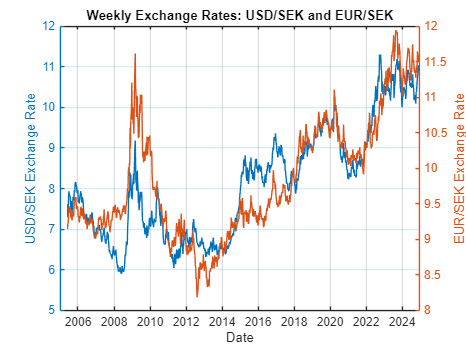

% 1. Plot time series with dual y-axes
figure(1) 
clf; 
yyaxis left 
plot(DataWeekly.Timestamp, DataWeekly.USDSEK)
ylabel('USD/SEK Exchange Rate')
yyaxis right
plot(DataWeekly.Timestamp, DataWeekly.EURSEK, 'Color', [0.8500 0.3250 0.0980]) % Orange line
ylabel('EUR/SEK Exchange Rate')
xlabel('Date')
title('Weekly Exchange Rates: USD/SEK and EUR/SEK')
grid on

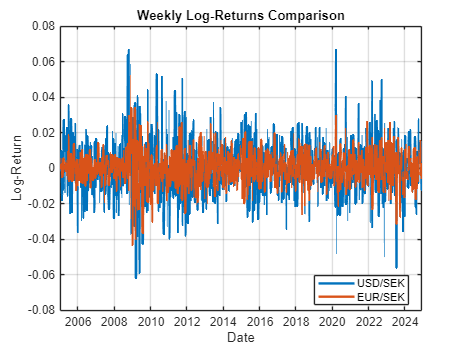


% 2. Plot logarithmic returns in one plot
figure(2)
clf; 

% Plot both series
plot(DataWeekly.Timestamp(2:end), r_usd_w, 'Color', [0 0.4470 0.7410], 'LineWidth', 2) % Blue
hold on
plot(DataWeekly.Timestamp(2:end), r_eur_w, 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 2) % Orange
hold off

% Formatting
title('Weekly Log-Returns Comparison')
xlabel('Date')
ylabel('Log-Return')
legend('USD/SEK', 'EUR/SEK', 'Location', 'best')
grid on


% 3. Calculate average return, volatility, and CI (Annualized) 
% Average performance
mu_usd_w = mean(r_usd_w) * 52 * 100;
mu_eur_w = mean(r_eur_w) * 52 * 100;

% Annualized volatility (scaled by sqrt(52))
sigma_usd_w = std(r_usd_w) * sqrt(52) * 100;
sigma_eur_w = std(r_eur_w) * sqrt(52) * 100;

% Standard Error
Number_of_weeks = length(r_usd_w);  
SE_usd_w = std(r_usd_w) / sqrt(Number_of_weeks);
SE_eur_w = std(r_eur_w) / sqrt(Number_of_weeks);

% 95% Confidence Interval
CI_usd_w = [mean(r_usd_w) - 1.96*SE_usd_w, mean(r_usd_w) + 1.96*SE_usd_w] * 52 * 100;
CI_eur_w = [mean(r_eur_w) - 1.96*SE_eur_w, mean(r_eur_w) + 1.96*SE_eur_w] * 52 * 100;

% Daily Data Stats
mu_usd_d = mean(r_usd_d) * 52 * 100;
mu_eur_d = mean(r_eur_d) * 52 * 100;

sigma_usd_d = std(r_usd_d) * sqrt(52) * 100;
sigma_eur_d = std(r_eur_d) * sqrt(52) * 100;

Number_of_days = length(r_usd_d);  

SE_usd_d = std(r_usd_d) / sqrt(Number_of_days);
SE_eur_d = std(r_eur_d) / sqrt(Number_of_days);

CI_usd_d = [mean(r_usd_d) - 1.96*SE_usd_d, mean(r_usd_d) + 1.96*SE_usd_d] * 52 * 100;
CI_eur_d = [mean(r_eur_d) - 1.96*SE_eur_d, mean(r_eur_d) + 1.96*SE_eur_d] * 52 * 100;

## Task 1(b): Distribution Analysis (Normality Tests) 

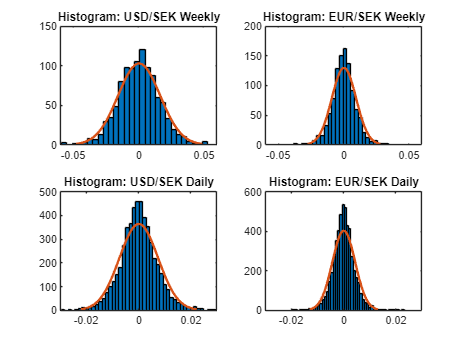

% i. Calculate Skewness and Excess Kurtosis 
skew_vals = [skewness(r_usd_w), skewness(r_eur_w), skewness(r_usd_d), skewness(r_eur_d)];
kurt_vals = [kurtosis(r_usd_w)-3, kurtosis(r_eur_w)-3, kurtosis(r_usd_d)-3, kurtosis(r_eur_d)-3];

% ii. Calculate Percentiles 
p_levels = [1, 5, 95, 99];
perc_matrix = [prctile(r_usd_w, p_levels) * 100; 
               prctile(r_eur_w, p_levels) * 100;
               prctile(r_usd_d, p_levels) * 100;
               prctile(r_eur_d, p_levels) * 100];

% Assign Results to Output Object
output.stat.mu = [mu_usd_w, mu_eur_w];
output.stat.sigma = [sigma_usd_w, sigma_eur_w];
output.stat.CI = [CI_usd_w; CI_eur_w];
output.stat.skew = skew_vals;
output.stat.kurt = kurt_vals;
output.stat.perc = perc_matrix;

% ii. Histograms with normal fit 
figure(3)
clf; 
% Weekly Plots
subplot(2,2,1); 
histfit(r_usd_w); 
title('Histogram: USD/SEK Weekly');
xlim([-0.06, 0.06]); 
subplot(2,2,2); 
histfit(r_eur_w); 
title('Histogram: EUR/SEK Weekly');
xlim([-0.06, 0.06]); 
% Daily Plots
subplot(2,2,3); 
histfit(r_usd_d); 
title('Histogram: USD/SEK Daily');
xlim([-0.03, 0.03]); 
subplot(2,2,4); 
histfit(r_eur_d); 
title('Histogram: EUR/SEK Daily');
xlim([-0.03, 0.03]); 

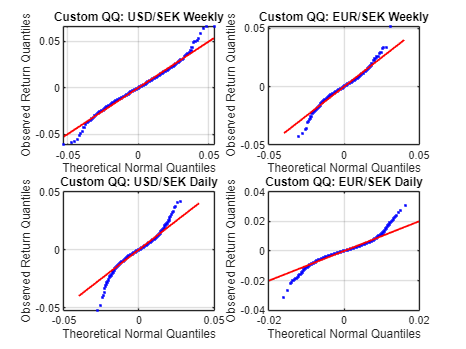


% iii. Manual QQ-plot Implementation
figure(4)
clf; 
titles = {'USD/SEK Weekly', 'EUR/SEK Weekly', 'USD/SEK Daily', 'EUR/SEK Daily'};
data_cell = {r_usd_w, r_eur_w, r_usd_d, r_eur_d}; 

for i = 1:4
    subplot(2,2,i)
    current_data = data_cell{i};
    
    % Step 1: Prepare Empirical Data 
    % Sort data from smallest to largest
    sorted_data = sort(current_data); 
    n = length(sorted_data);
    
    % Step 2: Generate Probability Points
    % Create n equally spaced points using the "continuity correction" (-0.5).
    % This ensures we don't try to calculate the quantile for exactly 0 or 1.
    prob_points = ((1:n) - 0.5) / n;
    
    % Step 3: Calculate Theoretical Quantiles
    % Map the probability points to the corresponding values on a Normal distribution
    % using the mean and standard deviation of your actual return data.
    theoretical_quantiles = norminv(prob_points, mean(current_data), std(current_data));
    
    % Step 4: Visualization
    % Plot Theoretical (X) vs Empirical (Y). If data is normal, it should form a straight line.
    plot(theoretical_quantiles, sorted_data, 'b.'); 
    hold on;
    
    % Add a 45-degree reference line (Slope = 1, Intercept = 0)
    % Deviations from this line indicate heavy tails (kurtosis) or skewness.
    ref_line = refline(1, 0); 
    ref_line.Color = 'r';
    ref_line.LineWidth = 1.5;
    
    % Labelling and Aesthetics
    title(['Custom QQ: ' titles{i}]);
    xlabel('Theoretical Normal Quantiles');
    ylabel('Observed Return Quantiles');
    grid on
end

## Task 2: Volatility Estimation

% Pre-allocate results structure
results.EWMA.objective_value = zeros(1, 2);
results.EWMA.estimated_lambda = zeros(1, 2);
results.GARCH.objective_value = zeros(1, 2);
results.GARCH.parameters = zeros(1, 6); % [Sigma_annual, Alpha, Beta] per asset
results.GARCH_VT.objective_value = zeros(1, 2);
results.GARCH_VT.parameters = zeros(1, 6);

% Prepare data
weekly_log_returns = [r_usd_w, r_eur_w];
[num_observations, num_assets] = size(weekly_log_returns);
asset_names = {'USDSEK', 'EURSEK'};

## Task 2a-d: Estimation Loop

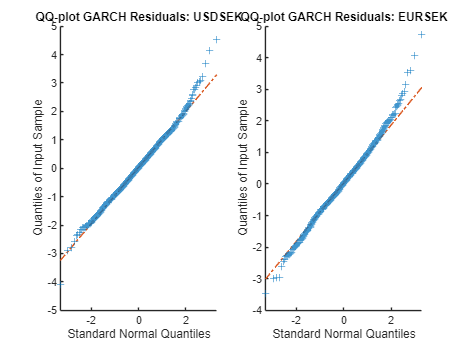

% Suppress fmincon output
options = optimoptions('fmincon', 'Display', 'none');
% Iterates through assets to perform EqWMA, EWMA, and GARCH estimations 

for asset_idx = 1:num_assets
    
    % Extract returns for the current asset
    current_asset_returns = weekly_log_returns(:, asset_idx);
    
    % Calculate unconditional (long-term) variance for VT and initialization
    unconditional_variance = var(current_asset_returns); 
    
    % --- Task 2(a): Equally Weighted Moving Average (EqWMA) ---
    % Rolling standard deviation * sqrt(52) for annualization 
    volatility_eqwma_30w = movstd(current_asset_returns, [29 0], 'Endpoints', 'discard') * sqrt(52);
    volatility_eqwma_90w = movstd(current_asset_returns, [89 0], 'Endpoints', 'discard') * sqrt(52);
    
    % --- Task 2(b): EWMA RiskMetrics (Fixed Lambda = 0.94) --- 
    decay_factor_rm = 0.94;
    variance_riskmetrics = zeros(num_observations, 1);
    variance_riskmetrics(1) = unconditional_variance;
    
    % Formula
    for t = 2:num_observations
        variance_riskmetrics(t) = (1 - decay_factor_rm) * current_asset_returns(t-1)^2 ...
                                + decay_factor_rm * variance_riskmetrics(t-1);
    end
    
    % --- Task 2(c): MLE Estimation (EWMA) --- 
    % Define objective function handle 
    obj_fun_ewma = @(lambda) ewma_negloglik(lambda, current_asset_returns, unconditional_variance);
    
    % Optimization limits for Lambda (0.01 to 0.99)
    initial_lambda_guess = 0.94;
    optimal_lambda = fmincon(obj_fun_ewma, initial_lambda_guess, [], [], [], [], 0.01, 0.99, [], options);
    
    % Store results
    results.EWMA.estimated_lambda(asset_idx) = optimal_lambda;
    results.EWMA.objective_value(asset_idx)  = -obj_fun_ewma(optimal_lambda);
    
    % --- Task 2(c): GARCH(1,1) Standard (No Variance Targeting) --- ]
    % Parameters: [omega, alpha, beta]
    alpha_init = 0.10;
    beta_init  = 0.85;
    omega_init = unconditional_variance * (1 - alpha_init - beta_init);
    
    initial_params_garch = [omega_init, alpha_init, beta_init];
    
    % Inequality constraints: Alpha + Beta <= 0.999
    A_ineq = [0 1 1]; 
    b_ineq = 0.999;
    lower_bounds = [1e-9, 0.001, 0.001];
    
    % Optimize
    [optimal_params_garch, nll_garch] = fmincon(@(p) garch_loglik(p, current_asset_returns), ...
                                                initial_params_garch, A_ineq, b_ineq, [], [], lower_bounds, [], [], options);
    
    % Save specific asset returns for Task 3
    if asset_idx == 1
        garch_params_usd = optimal_params_garch; 
        returns_usd = current_asset_returns;             
    elseif asset_idx == 2
        garch_params_eur = optimal_params_garch; 
        returns_eur = current_asset_returns;             
    end
    
    % Calculate implied long-term variance
    long_run_variance_implied = optimal_params_garch(1) / (1 - optimal_params_garch(2) - optimal_params_garch(3));
    
    % Store: [Annualized Volatility (%), Alpha, Beta]
    store_idx_start = (asset_idx-1) * 3 + 1;
    store_idx_end   = asset_idx * 3;
    
    results.GARCH.parameters(store_idx_start:store_idx_end) = ...
        [sqrt(long_run_variance_implied * 52) * 100, optimal_params_garch(2), optimal_params_garch(3)];
        
    results.GARCH.objective_value(asset_idx) = -nll_garch;
    
    % --- Task 2(c): GARCH(1,1) With Variance Targeting (VT)
    initial_params_vt = [0.1, 0.85]; % [alpha, beta]
    
    % Constraint: alpha + beta <= 0.999
    A_vt = [1 1]; 
    b_vt = 0.999;
    lb_vt = [0.001 0.001];
    
    [optimal_params_vt, nll_vt] = fmincon(@(p) garch_loglik_vt(p, current_asset_returns, unconditional_variance), ...
                                          initial_params_vt, A_vt, b_vt, [], [], lb_vt, [], [], options);
    
    % Store results
    results.GARCH_VT.parameters(store_idx_start:store_idx_end) = ...
        [sqrt(unconditional_variance * 52) * 100, optimal_params_vt(1), optimal_params_vt(2)];
        
    results.GARCH_VT.objective_value(asset_idx) = -nll_vt;
    
    % --- Task 2(d): Standardization and QQ-plots 
    % Calculate conditional variance with optimal GARCH parameters
    [~, conditional_variance_garch] = garch_loglik(optimal_params_garch, current_asset_returns);
    
    % Standardized residuals
    standardized_residuals = current_asset_returns ./ sqrt(conditional_variance_garch);
    
    figure(5)
    subplot(1, 2, asset_idx)
    qqplot(standardized_residuals)
    title(['QQ-plot GARCH Residuals: ' asset_names{asset_idx}])
end

## Task 2 Results: Visualization and Output

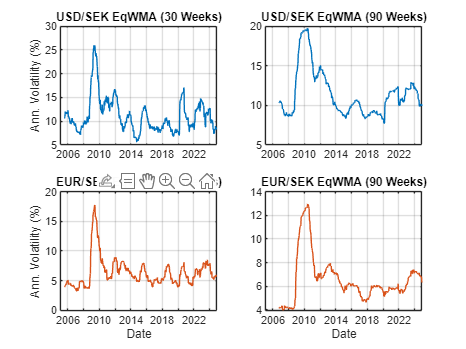

% Reconstruct volatility paths for plotting
vol_paths.USD.EqWMA_30 = movstd(weekly_log_returns(:,1), [29 0], 'Endpoints', 'discard') * sqrt(52) * 100;
vol_paths.USD.EqWMA_90 = movstd(weekly_log_returns(:,1), [89 0], 'Endpoints', 'discard') * sqrt(52) * 100;
vol_paths.EUR.EqWMA_30 = movstd(weekly_log_returns(:,2), [29 0], 'Endpoints', 'discard') * sqrt(52) * 100;
vol_paths.EUR.EqWMA_90 = movstd(weekly_log_returns(:,2), [89 0], 'Endpoints', 'discard') * sqrt(52) * 100;

% Helper to reconstruct volatility path from parameters
get_ewma_path = @(r, lam) sqrt(filter(1-lam, [1 -lam], r.^2, r(1)^2 * (1-lam))) * sqrt(52) * 100;

% RiskMetrics paths (Lambda = 0.94)
vol_paths.USD.RM = get_ewma_path(weekly_log_returns(:,1), 0.94);
vol_paths.EUR.RM = get_ewma_path(weekly_log_returns(:,2), 0.94);

% Estimated EWMA paths
vol_paths.USD.EWMA = get_ewma_path(weekly_log_returns(:,1), results.EWMA.estimated_lambda(1));
vol_paths.EUR.EWMA = get_ewma_path(weekly_log_returns(:,2), results.EWMA.estimated_lambda(2));

% GARCH paths (Standard)
reconstruct_garch = @(r, params) garch_loglik([ ( (params(1)/100/sqrt(52))^2 * (1-params(2)-params(3)) ), params(2), params(3)], r);

[~, var_garch_usd] = reconstruct_garch(weekly_log_returns(:,1), results.GARCH.parameters(1:3));
vol_paths.USD.GARCH = sqrt(var_garch_usd) * sqrt(52) * 100;

[~, var_garch_eur] = reconstruct_garch(weekly_log_returns(:,2), results.GARCH.parameters(4:6));
vol_paths.EUR.GARCH = sqrt(var_garch_eur) * sqrt(52) * 100;

dates = DataWeekly.Timestamp(2:end); % Aligns with returns

% Figure 8: EqWMA (2x2) 
figure(8)
clf;
% USD 30 Weeks (Pad with 29 NaNs)
subplot(2,2,1)
plot(dates, [nan(29,1); vol_paths.USD.EqWMA_30]) 
title('USD/SEK EqWMA (30 Weeks)')
ylabel('Ann. Volatility (%)')
grid on
xlim([dates(1) dates(end)])
% USD 90 Weeks (Pad with 89 NaNs)
subplot(2,2,2)
plot(dates, [nan(89,1); vol_paths.USD.EqWMA_90]) 
title('USD/SEK EqWMA (90 Weeks)')
grid on
xlim([dates(1) dates(end)])
% EUR 30 Weeks (Pad with 29 NaNs)
subplot(2,2,3)
plot(dates, [nan(29,1); vol_paths.EUR.EqWMA_30], 'Color', [0.85 0.32 0.1]) 
title('EUR/SEK EqWMA (30 Weeks)')
ylabel('Ann. Volatility (%)')
xlabel('Date')
grid on
xlim([dates(1) dates(end)])
% EUR 90 Weeks (Pad with 89 NaNs)
subplot(2,2,4)
plot(dates, [nan(89,1); vol_paths.EUR.EqWMA_90], 'Color', [0.85 0.32 0.1]) 
title('EUR/SEK EqWMA (90 Weeks)')
xlabel('Date')
grid on
xlim([dates(1) dates(end)])

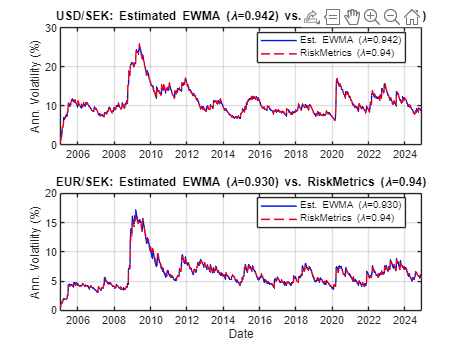


% Figure 9: EWMA Models (RiskMetrics vs. Estimated)
figure(9)
clf;
% --- USD/SEK Comparison ---
subplot(2,1,1)
% Plot 1: Estimated EWMA (Solid Blue)
plot(dates, vol_paths.USD.EWMA, 'Color', [0.0 0.1 0.9], 'LineWidth', 1.2)
hold on
% Plot 2: RiskMetrics Lambda=0.94 (Dashed Red)
plot(dates, vol_paths.USD.RM, 'Color', [0.9 0.0 0.1], 'LineStyle', '--', 'LineWidth', 1.2)
hold off
title(['USD/SEK: Estimated EWMA (\lambda=' num2str(results.EWMA.estimated_lambda(1), '%.3f') ') vs. RiskMetrics (\lambda=0.94)'])
ylabel('Ann. Volatility (%)')
legend(['Est. EWMA (\lambda=' num2str(results.EWMA.estimated_lambda(1), '%.3f') ')'], 'RiskMetrics (\lambda=0.94)', 'Location', 'best')
grid on
xlim([dates(1) dates(end)])

% --- EUR/SEK Comparison ---
subplot(2,1,2)
% Plot 1: Estimated EWMA (Solid Blue)
plot(dates, vol_paths.EUR.EWMA, 'Color', [0.0 0.1 0.9], 'LineWidth', 1.2)
hold on
% Plot 2: RiskMetrics Lambda=0.94 (Dashed Red)
plot(dates, vol_paths.EUR.RM, 'Color', [0.9 0.0 0.1], 'LineStyle', '--', 'LineWidth', 1.2)
hold off
title(['EUR/SEK: Estimated EWMA (\lambda=' num2str(results.EWMA.estimated_lambda(2), '%.3f') ') vs. RiskMetrics (\lambda=0.94)'])
ylabel('Ann. Volatility (%)')
xlabel('Date')
legend(['Est. EWMA (\lambda=' num2str(results.EWMA.estimated_lambda(2), '%.3f') ')'], 'RiskMetrics (\lambda=0.94)', 'Location', 'best')
grid on
xlim([dates(1) dates(end)])

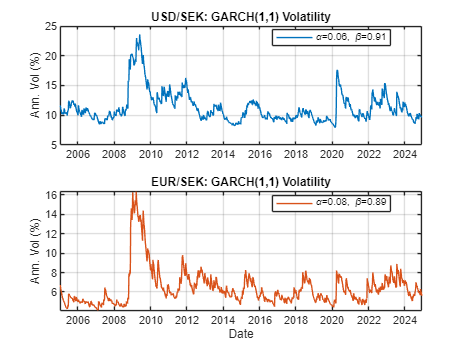


% Figure 10: GARCH(1,1) 
figure(10)
clf;
subplot(2,1,1)
plot(dates, vol_paths.USD.GARCH)
title('USD/SEK: GARCH(1,1) Volatility')
ylabel('Ann. Vol (%)')
grid on
xlim([dates(1) dates(end)])
legend(['\alpha=' num2str(results.GARCH.parameters(2),'%.2f') ', \beta=' num2str(results.GARCH.parameters(3),'%.2f')], 'Location', 'best')
subplot(2,1,2)
plot(dates, vol_paths.EUR.GARCH, 'Color', [0.85 0.32 0.1])
title('EUR/SEK: GARCH(1,1) Volatility')
ylabel('Ann. Vol (%)')
xlabel('Date')
grid on
xlim([dates(1) dates(end)])
legend(['\alpha=' num2str(results.GARCH.parameters(5),'%.2f') ', \beta=' num2str(results.GARCH.parameters(6),'%.2f')], 'Location', 'best')


% Assign Volatility Results to Output Object
output.EWMA.obj = [results.EWMA.objective_value];
output.EWMA.param = results.EWMA.estimated_lambda;
output.GARCH.obj = [results.GARCH.objective_value];
output.GARCH.objVT = [results.GARCH_VT.objective_value];
output.GARCH.param = [results.GARCH.parameters]; % omega1, a1,b1, omega2, a2,b2
output.GARCH.objVT = [results.GARCH_VT.objective_value ];
output.GARCH.paramVT = [results.GARCH_VT.parameters]; % omega1, a1,b1, omega2, a2,b2

## Task 3: Correlation and Bivariate Copulas 

% --- 1. Calculate Residuals 
% Use GARCH parameters and returns from Task 2 loop
[~, variance_usd] = garch_loglik(garch_params_usd, returns_usd); 
[~, variance_eur] = garch_loglik(garch_params_eur, returns_eur);

% Standardized residuals: epsilon = return / conditional_std_dev
residuals_usd = returns_usd ./ sqrt(variance_usd);
residuals_eur = returns_eur ./ sqrt(variance_eur);

## Task 3(a)-(b): Correlation and Autocorrelation 

% 3a: Pearson Linear Correlation
output.stat.corr = corr(returns_usd, returns_eur);

% 3b: Autocorrelation (lag 1-5) 
autocorr_usd = zeros(5,1);
autocorr_eur = zeros(5,1);
for lag = 1:5
    % Correlation between series and lagged version
    autocorr_usd(lag) = corr(returns_usd(lag+1:end), returns_usd(1:end-lag));
    autocorr_eur(lag) = corr(returns_eur(lag+1:end), returns_eur(1:end-lag));
end
output.stat.acorr = [autocorr_usd, autocorr_eur];

## Task 3(c): Copula Fitting (IFM Method) 

% Transform residuals to uniform domain [0,1]
u_usd = normcdf(residuals_usd);
u_eur = normcdf(residuals_eur);
u_data = [u_usd, u_eur];

% List of copulas to test
copula_types = {'Gaussian', 't', 'Gumbel', 'Clayton', 'Frank'};
log_likelihood_copulas = zeros(1, 5);

for i = 1:5
    try
        if strcmp(copula_types{i}, 't')
            % Separate Rho and DF for Student-t
            [rho, df] = copulafit('t', u_data);
            pdf_vals = copulapdf('t', u_data, rho, df);
        else
            % Single parameter vector for others
            param = copulafit(copula_types{i}, u_data);
            pdf_vals = copulapdf(copula_types{i}, u_data, param);
        end
        
        % Calculate Log-Likelihood
        log_likelihood_copulas(i) = sum(log(pdf_vals));
        
    catch
        log_likelihood_copulas(i) = -Inf; % Fallback for optimization failure
    end
end
% Store results
output.copulaLogL = log_likelihood_copulas;

% Identify best performing copula
[maxLL, bestIdx] = max(log_likelihood_copulas);
best_copula_name = copula_types{bestIdx};

## Task 3(d)-(e): Simulation and Residual Inversion 

% --- 4. Simulation Logic ---
if strcmp(best_copula_name, 't')
    [rho_best, df_best] = copulafit('t', u_data);
    u_simulated = copularnd('t', rho_best, df_best, 10000);
else
    best_copula_params = copulafit(best_copula_name, u_data);
    u_simulated = copularnd(best_copula_name, best_copula_params, 10000);
end

% Transform back to residuals
residuals_simulated = norminv(u_simulated);

## Task 3(f): Forecast Scenarios 

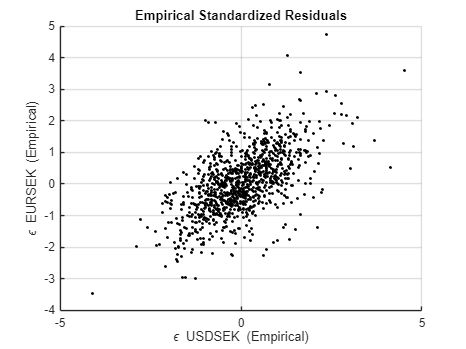

% One-step ahead volatility forecast (sigma_t+1) Formula: sigma_t+1^2 = omega + alpha*r_t^2 + beta*sigma_t^2
next_variance_usd = garch_params_usd(1) + garch_params_usd(2)*returns_usd(end)^2 + garch_params_usd(3)*variance_usd(end);
next_variance_eur = garch_params_eur(1) + garch_params_eur(2)*returns_eur(end)^2 + garch_params_eur(3)*variance_eur(end);

% Create simulated returns for next week
sim_returns_usd = sqrt(next_variance_usd) * residuals_simulated(:,1);
sim_returns_eur = sqrt(next_variance_eur) * residuals_simulated(:,2);

% --- 5. Visualization (Complete Set) ---
% Plot 1: Empirical Residuals 
figure(11)
clf; 
scatter(residuals_usd, residuals_eur, 6, 'k', 'filled') 
grid on; 
xlabel('\epsilon USDSEK (Empirical)'); 
ylabel('\epsilon EURSEK (Empirical)');
title('Empirical Standardized Residuals');

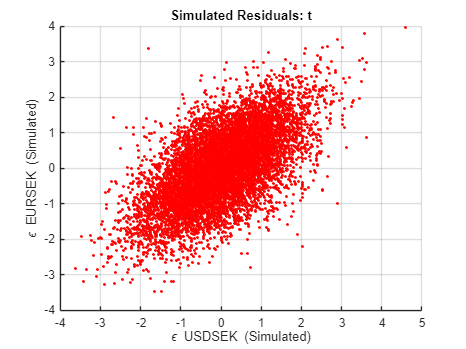


% Plot 2: Simulated Residuals 
figure(12)
clf; 
scatter(residuals_simulated(:,1), residuals_simulated(:,2), 6, 'r', 'filled') 
grid on; 
xlabel('\epsilon USDSEK (Simulated)'); 
ylabel('\epsilon EURSEK (Simulated)');
title(['Simulated Residuals: ' best_copula_name]);

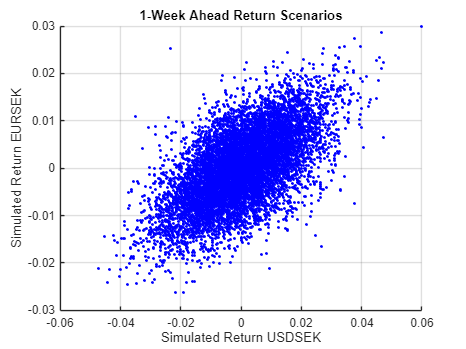


% Plot 3: One-Week Ahead Return Scenarios
figure(13)
clf; 
scatter(sim_returns_usd, sim_returns_eur, 6, 'b', 'filled') 
grid on; 
xlabel('Simulated Return USDSEK'); 
ylabel('Simulated Return EURSEK');
title('1-Week Ahead Return Scenarios');


% Output Results
printResults(output,true);

## Helper functions

function [LL, sig2] = garch_loglik(p, r)
    omega = p(1); alpha = p(2); beta = p(3);
    T = length(r);
    sig2 = zeros(T,1);
    sig2(1) = var(r); 
    for t = 2:T
        sig2(t) = omega + alpha*r(t-1)^2 + beta*sig2(t-1);
    end
    LL = -sum(-0.5*log(2*pi) - 0.5*log(sig2) - 0.5*(r.^2 ./ sig2));
end

function LL = garch_loglik_vt(p, r, V)
    alpha = p(1); beta = p(2);
    omega = V * (1 - alpha - beta);
    LL = garch_loglik([omega, alpha, beta], r);
end

function nll = ewma_negloglik(lambda, ret, sig2_init)
    T = length(ret);
    sig2 = zeros(T, 1);
    sig2(1) = sig2_init;
    
    % Loop ensures we use ret(t-1) to calculate sig2(t)
    for t = 2:T
        sig2(t) = (1-lambda) * ret(t-1)^2 + lambda * sig2(t-1);
    end
    
    % Calculate Negative Log Likelihood
    ll_vec = -0.5 * (log(2*pi) + log(sig2) + (ret.^2)./sig2);
    nll = -sum(ll_vec);
end